# Integración Numérica 

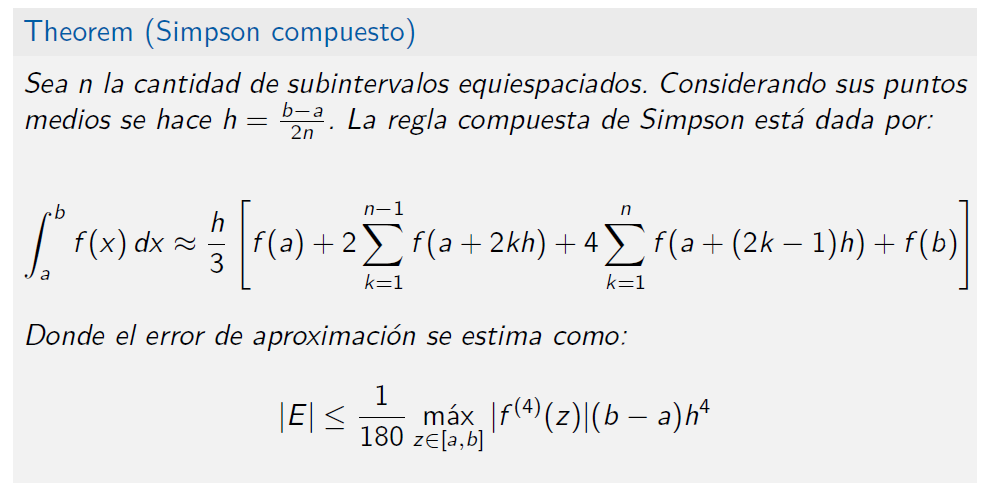

f = @(x) sin(x)./x;
a = 1; b = 3;
n = 5;

resultado = reglaTrapecioCompuesta(f, a, b, n)

resultado = 0.9020


% Integral exacta
excta = integral(f, a, b)

excta = 0.9026

**Reglas simples (cuadraturas del trapecio y de Simpson 1/3)**

f = @(x) sin(x)./x;
format long 

It = trapecioSimple(f, 1, 3)

It =    0.888510987494519



Ism = simpsonSimple(f, 1, 3)

Ism =    0.902368613715294



% Valor "exacto"

Iexacta = integral(f, 1, 3)

Iexacta =    0.902569457632285


**Ejemplos de la Presentación**

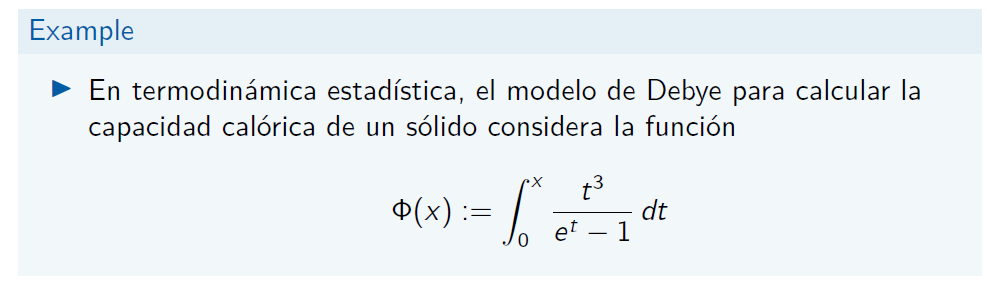

% con x = 1
x = 1;
n = 4; % cuadratura de 4 puntos de GL

Iphi = QuadGaussLeg(@(t) (t.^3)./(exp(t)-1), n, 0, x)

Iphi =    0.224805187479298



% exacta
integral(@(t) (t.^3)./(exp(t)-1), 0, x)

ans =    0.224805188025938


*Ejemplo 1:* 

format long; 
f=@(x) exp(-x^2);
Itrapc = trapecioCompuesto(f,-2,2, 4)

Itrapc =    1.754074521231619


*Ejemplo 2: *

Isimpc = ReglaCompuestaSimpson(f,-2,2, 3)

Isimpc =    1.767435412165737


*Ejemplo 2 (en clase):* 

format long; 
f = @(x) exp(-x.^2);

Itrapc = trapecioCompuesto(f, 0, 4, 4)

Itrapc =    0.886318546131851


Isimpc = ReglaCompuestaSimpson(f, 0, 4, 2) % n = 2

Isimpc =    0.836214264738253



%-------
Iexacta = integral(f, 0 , 4)

Iexacta =    0.886226911789569


***Ejercicio 6.1.3***

format long;
g=@(x) cos(x.^2);
a=0; b=pi;
m=4;
% Trapecio Compuesto 
I1 = trapecioCompuesto(g,a,b,m)

I1 =    0.649760900266590


I2 = ReglaCompuestaSimpson(g,a,b,m)

I2 =    0.586908102252393



% Integral "exacta"
Iexacta= integral(g,a,b)

Iexacta =    0.565693513606683


***Ejemplo Gauss 2 puntos simple***

f=@(t) exp(-t.^2);
IgaussL= IGauss2Leg(f, -2, 2)

IgaussL =    1.054388552462907


***Ejemplo regla compuesta Gauss 2 puntos:***

[IgaussLC]= IGauss2LC(f, -2, 2, 4)

IgaussLC =    1.764523022917831



% Valor exacto
Iexactag=integral(@(t) exp(-t.^2), -2, 2)

Iexactag =    1.764162781524843



% Comparando con la regla compuesta trapecio

[Itrap] = trapecioCompuesto(f,-2,2,4)

Itrap =    1.754074521231619


f = @(x) exp(x.^2);

I = IGauss2Leg(f, -1, 1)

I = 2.7912


Iexacta = integral(f, -1, 1)

Iexacta = 2.9253

f=@(t) cos(t.^2);
%[IgaussLC]= IGauss2LC(f, 0, pi, 2)

I2 = GaussLegC(f, 2, 0, pi, 3)

I2 =    0.410673441043876



% Valor exacto
Iexactag=integral(@(t) cos(t.^2), 0, pi)

Iexactag =    0.565693513606683



% Comparando con la regla compuesta trapecio

[Itrap] = trapecioCompuesto(f,0,pi,4)

Itrap =    0.649760900266590


**Polinomios de Legendre:**

format rat;
P = LegendrePolyn(2)

P =        3/2            0             -1/2     



format; 
r = sort(roots(P))'

r =    -0.5774    0.5774



L0 = Lk(1,r)

L0 =    -0.8660    0.5000


L1 = Lk(2,r)

L1 =     0.8660    0.5000


%L2 = Lk(3,r)

%diff(polyval(Lk(1,r)),[-1 1])

%W = WGaussLeg(2)

%Int = polyint([1 0])

%p = [1 0];

%q = polyint(L0)

w0 = diff(polyval(polyint(L0),[-1 1]))

w0 = 1.0000


W = WGaussLeg(2)

W =     1.0000    1.0000


**Ejemplo de cuadratura de Gauss-Legendre (simple)**

f = @(x) exp(x.^2);

% Usaremos la cuadratura de GL de dos puntos 
Iapprox = QuadGaussLeg(f, 2, -1, 1)

Iapprox = 2.7912


% Integral "exacta"
Iexacta = integral(f, -1, 1)

Iexacta = 2.9253

**Ejemplo de Gauss-Legendre (simple)**

g = @(t) 1./(1+t.^2);

for i = 2:20
    I = QuadGaussLeg(g, i, -5, 5)
end

I = 1.0714

I = 4.7917

I = 1.8546

I = 3.5347

I = 2.3085

I = 3.0806

I = 2.5406

I = 2.8935

I = 2.6519

I = 2.8123

I = 2.7035

I = 2.7762

I = 2.7272

I = 2.7601

I = 2.7379

I = 2.7528

I = 2.7428

I = 2.7495

I = 2.7450


Iexacc = integral(g, -5, 5)

Iexacc = 2.7468

**Otro ejemplo:**

format long 
f = @(x) sin(x)./x;

Iapprox = QuadGaussLeg(f, 2, 0, 1)

Iapprox =    0.946041136897821



% Integral "exacta":

Iexacta = integral(f, 0, 1)

Iexacta =    0.946083070367183



% Error relativo en la aprox de 2 puntos GL
errgl2 = abs(Iexacta - Iapprox)/abs(Iexacta)

errgl2 =      4.432324250970375e-05



% Calculemos la aproximación por Simpson 1/3
IapproxS = simpsonSimple(f, 0, 1)

IapproxS =    NaN


f = @(x) exp(-x.^2);

% Cuadratura de dos puntos GL
IGL2 = QuadGaussLeg(f, 2, 0, 3)

IGL2 =    1.009105074049620



% Integral exacta
Iexacta = integral(f, 0, 3)

Iexacta =    0.886207348259521


Ejemplo en clase:

f = @(x) sin(x)./x;

% Integral "exacta":
format long
Iexacta = integral(f, 0, 1)

Iexacta =    0.946083070367183



% Integral por cuadraturas de Gauss-Legendre (simples):

%% Dos puntos:
IGL2 = QuadGaussLeg(f, 2, 0, 1)

IGL2 =    0.946041136897821



%% Tres puntos:
IGL3 = QuadGaussLeg(f, 3, 0, 1) 

IGL3 =    0.946083134078472



%% cuatro puntos:
IGL4 = QuadGaussLeg(f, 4, 0, 1)

IGL4 =    0.946083070311256



%% con for:
for n = 2:20
    I = QuadGaussLeg(f, n, 0, 1); 
end
I

I =    0.946083069740161


**Ejemplo:** cuadratura compuesta de GL de dos puntos

format long
f = @(x) exp(-x.^2);

IGL2C = GaussLegC(f, 2, 0, 1, 3)

IGL2C =    0.746819962615706



Iexacta = integral(f, 0, 1)

Iexacta =    0.746824132812427


# Funciones

***Trapecio simple***

function It = trapecioSimple(f, a, b)
% Inputs: función f, a, b puntos
% Output: aproximación de la integral de f en [a, b]

It = (b-a)/2 * (f(a) + f(b));

end

***Simpson 1/3 simple***

function Ism = simpsonSimple(f, a, b)
% Inputs: función f, a, b puntos
% Output: aproximación de la integral de f en [a, b]

c = (a+b)/2;

Ism = (b-a)/6 * (f(a) + 4*f(c) + f(b));
end

***Trapecio compuesto***

function [Itrapc] = trapecioCompuesto(f,a,b,m)
% Aproximar integrales usando trapecio compuesto
% Entradas:     f ---- funcion a integrar
%           [a,b] ---- intervalo de integracion
%               m ---- cantidad de nodos de interpolacion
% Salida:       Itrapc ---- valor de la integral definida aproximado

h = (b-a)/m;
s = 0;

for i = 1:m-1
    s = s + f(a+i*h);
end

Itrapc = (h/2)*(f(a) + 2*s + f(b));

end

**Regla trapecio compuesto **

function resultado = reglaTrapecioCompuesta(f, a, b, n)
% f: función a integrar
% a: límite inferior de integración
% b: límite superior de integración
% n: número de subintervalos

h = (b - a) / n; % ancho de cada subintervalo
x = a:h:b; % puntos de evaluación
y = f(x); % evaluación de la función en los puntos

resultado = h * (sum(y) - (y(1) + y(end))/2); % cálculo de la integral aproximada
end


***Simpson 1/3 Compuesto***

function [Isimpc] = ReglaCompuestaSimpson(f,a,b,m)
%Este programa aproxima integrales utilizando la regla compuesta de
%Simpson. 
%Entradas:    f ---- funcion a integrar
%          [a,b]---- intervalo de integracion
%             2m ---- cantidad de nodos de interpolacion 
% Salida:      Isimpc ---- valor de la integral definida aproximado

h = (b-a)/(2*m);
s = 0; 
s1 = 0;

    for j=1:m-1
        s = s + f(a+2*j*h);
    end

    for j=1:m
        s1 = s1 + f(a+(2*j-1)*h);
    end
Isimpc = (h/3)*(f(a) + 2*s + 4*s1 + f(b));
end

***Cuadratura Gaussiana simple de dos puntos***

function [IgaussL]= IGauss2Leg(f, a, b)
z1=-sqrt(3)./3;
z2=-z1;
IgaussL = (b-a)./2 * (f(((b-a)./2)*z1+(a+b)./2) +f(((b-a)./2)*z2+(a+b)./2));
end

***Cuadratura Gaussiana compuesta de 2 puntos***

function [IgaussLC]= IGauss2LC(f, a, b, m)
h=(b-a)/m;
X=a:h:b;
IgaussLC=0;
for k=1:length(X)-1
    IgaussLC = IgaussLC + IGauss2Leg(f, X(k), X(k+1));
end
end

***Polinomios de Legendre***

function P = LegendrePolyn(n)
% Input: n natural >= 0
% Output: P polinomio n-ésimo de Legendre

if n == 0
    P = 1;
elseif n == 1
    P= [1 0];
else
    P0 = 1;
    P1 = [1 0];
    
    for k = 2:n
        
        Q1 = conv([1 0], P1);   % x*P1(x) 
        Q0 = [zeros(1, length(Q1)-length(P0)), P0];
        
        P = (1./k).*((2.*k-1).* Q1 - (k-1).*Q0);
        P0 = P1;
        P1 = P;
    end
end
end

$L_k(x)$*** polinomios cardinales de Lagrange:***

function [c] = Lk(k,x)
% Polinomio L_{k-1} cardinal de Lagrange
% En nuestro caso sería k-1 
% Inputs: k -- (k-1) polinomio cardinal de Lagrange,
% x = vector que almacena el conjunto soporte {x1,x2,...,xn}
% Output: c = polinomio (MATLAB) cardinal (k-1)ésimo de Lagrange
npts=length(x);
c=1;
for i=[1:(k-1), (k+1):npts] % i \neq k
    den = x(k) - x(i);
    c = conv(c, [1/den, - x(i)/den]);
end
end

***Pesos de Gauss-Legendre***

function W = WGaussLeg(n)
% Inputs: n grado del polinomio de Legendre
% Output: W pesos de la cuadratura 
% utilizando como nodos los ceros del polinomio de Legendre

r = sort(roots(LegendrePolyn(n)))';

W = zeros(1, n);

for k = 1:n 
    W(k) = diff(polyval(polyint(Lk(k,r)),[-1 1]));
end

end

***Cuadratura de Gauss-Legendre***

function I = QuadGaussLeg(f, n, a, b)
% Inputs: f función, n grado del polinomio de Legendre,
% [a, b] intervalo de integración
% Output: aproximación numérica de la integral de f en [a, b]
% utilizando como nodos los ceros del polinomio de Legendre

% Almacenamos los ceros del n-ésimo
% polinomio de Legendre en un vector fila 'r':
r = sort(roots(LegendrePolyn(n)))';

% Almacenaremos los pesos de la cuadratura en un vector nulo 'W':
W = zeros(1, n);

% Iniciamos declarando 'I = 0':
I = 0;

for k = 1:n
    % Calculamos los pesos con los polinomios cardinales de Lagrange
    W(k) = diff(polyval(polyint(Lk(k,r)),[-1 1]));
    
    % Actualizamos 'I' usando el cambio de variable para trabajar
    % en el intervalo [a, b]:
    I = I + (b-a)./2 * (W(k).*f((b-a)./2 * r(k) + (a+b)./2));
end
end

***Cuadratura compuesta de Gauss-Legendre***

function I = GaussLegC(f, n, a, b, m)
% Inputs: f función, n grado del polinomio de Legendre,
% [a, b] intervalo de integración, m cantidad de intervalos
% Output: aproximación numérica de la integral de f en [a, b]
% utilizando como nodos los ceros del polinomio de Legendre

% Paso entre los nodos:
h=(b-a)/m;

% Nodos:
X = a:h:b;

% Iniciando con 'I = 0':
I = 0;

for k=1:length(X)-1
    I = I + QuadGaussLeg(f, n, X(k), X(k+1));
end
end